clear;
Model_scripts = {'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
address = Model_scripts;
WIS_Short=[];WIS_Long=[];
for number = 1:numel(address)
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal_retro")
%  cd("E:\Dong\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
     cd (address{number});
     load('cross_WIS.mat');
     WIS4=WIS4(1:15,1:7);
     WIS_Short(number,:,:) = WIS1;
     WIS_Long(number,:,:)  = WIS4;
     WIS11 = sort(WIS1(:));
     Mean_Short(number,:)  = mean(mean(WIS11(2:end-1)));
     WIS44 = sort(WIS4(:));
     Mean_Long(number,:)   = mean(mean(WIS44(2:end-3)));
     Mean_year_Short(number,:)  = mean(WIS1);
     Mean_year_Long(number,:)   = mean(WIS4);
end

## compare ensemble

% ensemble mean
model_number={[1],[2:5],[6:11],[12:15],[16]};
for i=1:5
  Ensemble_Short_mean (i)  = mean (Mean_Short(model_number{i}));
  Ensemble_Long_mean (i)  = mean (Mean_Long(model_number{i}));
  Ensemble_Short{i}=WIS_Short(model_number{i},:,:);
  Ensemble_Long{i}=WIS_Long(model_number{i},:,:);
end



## wis long

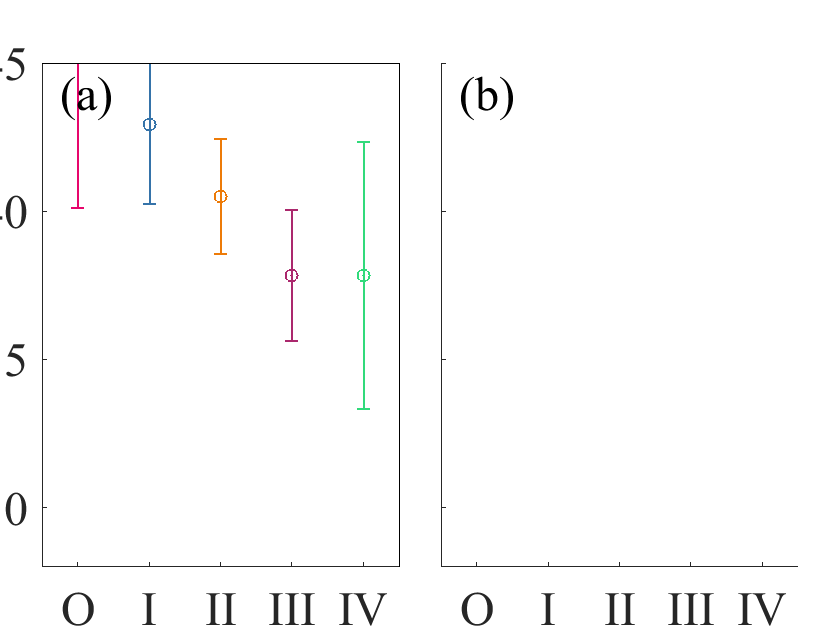

colors =[0.906308150649733	0.0225125927402318	0.422885689100085
0.208934922426023	0.450137696965896	0.662009598359135
0.928313062314188	0.484296511212103	0.0319910157625669
0.669175304534394	0.156404952226563	0.428252992979386
0.190433267179954	0.855522805845911	0.482022061031856];
% figure;hold on;
close all;
Number_values = [56,224,336,224,56];
ha=tight_subplot(1,2,0.05,0.1,0.05);%hold on;
axes(ha(2));hold on;
for figs=1:5
    e1 = errorbar(figs,Ensemble_Long_mean(figs), std(Ensemble_Long{figs}(:))/sqrt(Number_values(figs)));set(e1,  'LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6,'color',colors(figs,:))
end
xlim([0.5 5.5]);ylim([28 45]);set(gca,"XTick",[1:1:5],"xticklabel",{'O','I','II','III','IV'});
% ylabel('WIS');
text(0.75,44,'(b)',"FontSize",24,'FontName','Times New Roman')
set(gca,'FontName','Times New Roman','FontSize',24);
set(gca,"YTick",[30:5:45],"yticklabel",{});

% xlabel('Ensemble models');box_off
%% wis short

axes(ha(1));hold on;
for figs=1:5
     e1 = errorbar(figs,Ensemble_Short_mean(figs), std(Ensemble_Short{figs}(:))/sqrt(Number_values(figs)));set(e1,  'LineWidth', 1, 'Marker', 'o', 'MarkerSize', 6,'color',colors(figs,:))
end
xlim([0.5 5.5]);ylim([28 45]);set(gca,"XTick",[1:1:5],"xticklabel",{'O','I','II','III','IV'});
ylabel('WIS');text(0.75,44,'(a)',"FontSize",24,'FontName','Times New Roman')
% xlabel('Ensemble models')
set(gca,'FontName','Times New Roman','FontSize',24);
%title('Short-term forecasting performance for Ensemble models')

set(gca,"YTick",[30:5:45],"yticklabel",{'30','35','40','45','50'});
% exportgraphics(gcf,'FigureS 3 Ensemble_Forecasting_performance_1.pdf','ContentType','vector')
box_off


figure;ha=tight_subplot(1,2,0.05,0.1,0.05);%hold on;
axes(ha(1));hold on;
violin(Ensemble_Short_mean,'xlabel',{'O','I','II','III','IV'},'facecolor',colors,'edgecolor','w',...
    'bw',0.3,...
'mc','k',...
'medc','r--')

b = 0.3000

same bandwidth bw = 0.3 used for all cols


ans =   1×5 Patch array:

    Patch    Patch    Patch    Patch    Patch


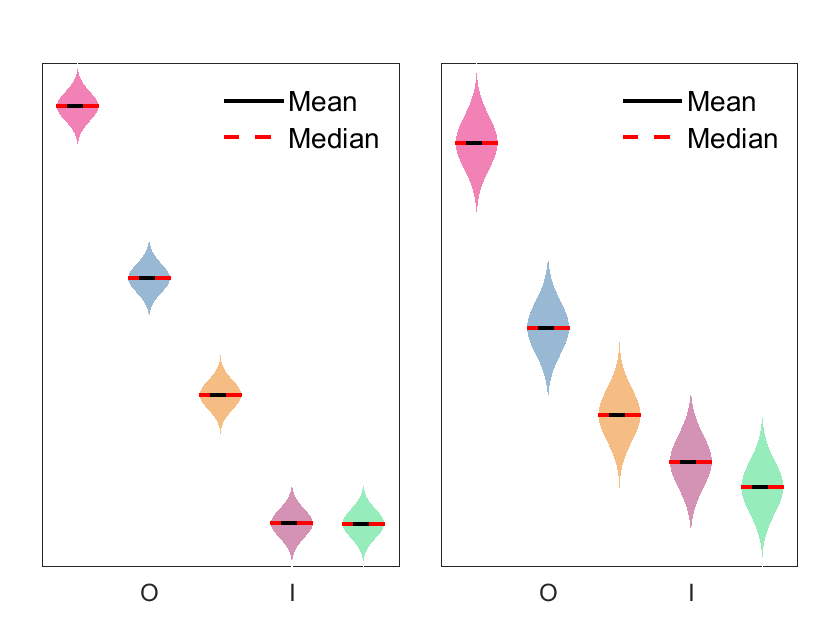

b = 0.3000

same bandwidth bw = 0.3 used for all cols


ans =   1×5 Patch array:

    Patch    Patch    Patch    Patch    Patch


axes(ha(2));hold on;
violin(Ensemble_Long_mean,'xlabel',{'O','I','II','III','IV'},'facecolor',colors,'edgecolor','w',...
'bw',0.3,...
'mc','k',...
'medc','r--')


%exportgraphics(gcf,sprintf('FigureS 3 Ensemble_Forecasting_performance_%d.pdf',1),'ContentType','vector')

% for figs=1:5
% boxchart(figs*ones(size(Ensemble_Long{figs}(:))), Ensemble_Long{figs}(:), 'BoxFaceColor', colors(figs,:),'Notch','off','MarkerSize',0.01,'MarkerStyle','.','MarkerColor','k','JitterOutliers','off','BoxWidth',0.4)
% end



% for figs=1:5
% boxchart(figs*ones(size(Ensemble_Short{figs}(:))), Ensemble_Short{figs}(:), 'BoxFaceColor', colors(figs,:),'Notch','off','MarkerSize',0.01,'MarkerStyle','.','MarkerColor','k','JitterOutliers','off','BoxWidth',0.4)
% end


## Make forecasting

Ensemble model I

model_number={[1],[2:5],[6:11],[12:15],[16]};
EN_valuesshort_CF  = [8,32,48,32,8];
EN_valueslong_CF   = [7,28,42,28,7];
yearshort_CF       =[2012,2013,2014,2015,2016,2017,2018,2019];
yearlong_CF        =[2012,2013,2014,2015,2016,2017,2018];
Ranks_short_CF=[];Ranks_Long_CF=[];

EN_valuesshort_P = [8,32,48,32,8];% [5,20,30,20,5];
EN_valueslong_P  = [7,28,42,28,7];%[5,20,30,20,5];
yearshort_P      = [2016,2017,2018,2019,2020,2021,2022,2023];
yearlong_P       = [2016,2017,2018,2019,2020,2021,2022];
Ranks_short_P=[];Ranks_Long_P=[];

Weights_long_CF=[];Weights_short_CF=[];Weights_long_P=[];Weights_short_P=[];
for ENmodel = 1:5
Ranks_short_CF{ENmodel} = Mean_year_Short(model_number{ENmodel},:);
Ranks_Long_CF{ENmodel}  = Mean_year_Long(model_number{ENmodel},:);

Ranks_short_P{ENmodel} = Mean_year_Short(model_number{ENmodel},1:length(yearshort_P));
Ranks_Long_P{ENmodel}  = Mean_year_Long(model_number{ENmodel},1:length(yearlong_P));

[~,C1S_CF]=sort(Ranks_short_CF{ENmodel}(:));[~,F1S_CF]=sort(C1S_CF(:)); Ranks_short_CF{ENmodel}=reshape(F1S_CF,length(model_number{ENmodel}),8);
[~,C1S_P]=sort(Ranks_short_P{ENmodel}(:));[~,F1S_P]=sort(C1S_P(:)); Ranks_short_P{ENmodel}=reshape(F1S_P,length(model_number{ENmodel}),length(yearshort_P));
% Table1s = string(round(Ranks_short_CF{ENmodel},2));Table2s = string(Ranks_short_CF{ENmodel});
[~,C1L_CF]=sort(Ranks_Long_CF{ENmodel}(:));[~,F1L_CF]=sort(C1L_CF(:)); Ranks_Long_CF{ENmodel}=reshape(F1L_CF,length(model_number{ENmodel}),7);
[~,C1L_P]=sort(Ranks_Long_P{ENmodel}(:));[~,F1L_P]=sort(C1L_P(:)); Ranks_Long_P{ENmodel}=reshape(F1L_P,length(model_number{ENmodel}),length(yearlong_P));

% Table1L = string(round(Ranks_short_CF{ENmodel},2));Table2L = string(Ranks_Long_CF{ENmodel});

for col=1:length(yearshort_CF)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_short_CF{ENmodel}(row,col)= rank_order_centroid_weighting(EN_valuesshort_CF(ENmodel),Ranks_short_CF{ENmodel}(row,col));
    end
end
for col=1:length(yearlong_CF)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_long_CF{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_CF(ENmodel),Ranks_Long_CF{ENmodel}(row,col));
    end
end
for col=1:length(yearshort_P)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_short_P{ENmodel}(row,col)= rank_order_centroid_weighting(EN_valuesshort_P(ENmodel),Ranks_short_P{ENmodel}(row,col));
    end
end
for col=1:length(yearlong_P)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_long_P{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_P(ENmodel),Ranks_Long_P{ENmodel}(row,col));
    end
end
sum(sum(Weights_short_CF{ENmodel}))
sum(sum(Weights_long_CF{ENmodel}))
sum(sum(Weights_short_P{ENmodel}))
sum(sum(Weights_long_P{ENmodel}))
end

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1.0000

ans = 1

ans = 1.0000

ans = 1

for ENmodel=5:5
N = 2000;
R_newPI_short{ENmodel}=zeros(N,8+52+7);R_newPI_Long{ENmodel}=zeros(N,53+52+7);R_newPI_shortCF{ENmodel}=zeros(N,8);R_newPI_LongCF{ENmodel}=zeros(N,53);
R_newPI_short1{ENmodel}=zeros(N,8);R_newPI_Long1{ENmodel}=zeros(N,8);R_newPI_shortCF1{ENmodel}=zeros(N,8);R_newPI_LongCF1{ENmodel}=zeros(N,8);
P_newPI_short{ENmodel}=zeros(N,8+52);P_newPI_Long{ENmodel}=zeros(N,52+52);
P_newPI_short1{ENmodel}=zeros(N,29);P_newPI_Long1{ENmodel}=zeros(N,29);
R_newPI_shortCF_F{ENmodel}=zeros(N,8);R_newPI_LongCF_F{ENmodel}=zeros(N,53);

R_newCI_short{ENmodel}=zeros(N,8);R_newCI_Long{ENmodel}=zeros(N,53);R_newCI_shortCF{ENmodel}=zeros(N,8);R_newCI_LongCF{ENmodel}=zeros(N,53);
P_newCI_short{ENmodel}=zeros(N,8);P_newCI_Long{ENmodel}=zeros(N,52); 

for row=1:numel(Model_scripts(model_number{ENmodel}))
  cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
% cd("D:\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    cd(Model_scripts{model_number{ENmodel}(row)});
    for col=1:length(yearshort_CF)
        load(sprintf('ABase_%d.mat',yearshort_CF(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        load(sprintf('PICF_Fore_ave_%d.mat',yearshort_CF(col)));
        if ENmodel == 1
            PIdataCF_Fore = PIdataCF;
        end
        R_newPI_short{ENmodel}   = R_newPI_short{ENmodel} + Weights_short_CF{ENmodel}(row,col).*PIdata(1:N,end-234-15-52-7:end-227-15);
        R_newPI_shortCF{ENmodel} = R_newPI_shortCF{ENmodel} + Weights_short_CF{ENmodel}(row,col).*PIdataCF(1:N,end-234-15:end-227-15);
        R_newPI_shortCF_F{ENmodel} = R_newPI_shortCF_F{ENmodel} + Weights_short_CF{ENmodel}(row,col).*PIdataCF_Fore(1:N,end-234-15:end-227-15);
%         R_newPI_short1{ENmodel}  = R_newPI_short1{ENmodel} + Weights_short{ENmodel}(row,col).*PIdata(1:N,end-241:end-234);
%         P_newPI_short1{ENmodel}  = P_newPI_short1{ENmodel} + Weights_short{ENmodel}(row,col).*PIdata(1:N,end-80:end-52);
    end
    for col=1:length(yearlong_CF)
        load(sprintf('ABase_%d.mat',yearlong_CF(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        load(sprintf('PICF_Fore_ave_%d.mat',yearshort_CF(col)));
        if ENmodel == 1
            PIdataCF_Fore = PIdataCF;
        end
        R_newPI_Long{ENmodel}    = R_newPI_Long{ENmodel} + Weights_long_CF{ENmodel}(row,col).*PIdata(1:N,end-234-15-52-7:end-182-15);
        R_newPI_LongCF{ENmodel}  = R_newPI_LongCF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*PIdataCF(1:N,end-234-15:end-182-15);
        R_newPI_LongCF_F{ENmodel}= R_newPI_LongCF_F{ENmodel} + Weights_long_CF{ENmodel}(row,col).*PIdataCF_Fore(1:N,end-234-15:end-182-15);
    end
    for col=1:length(yearshort_P)
        load(sprintf('ABase_%d.mat',yearshort_P(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        P_newPI_short{ENmodel}   = P_newPI_short{ENmodel}  + Weights_short_P{ENmodel}(row,col).*PIdata(1:N,end-52-52:end-45);
    end
    for col=1:length(yearlong_P)
        load(sprintf('ABase_%d.mat',yearlong_P(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        P_newPI_Long{ENmodel}    = P_newPI_Long{ENmodel} + Weights_long_P{ENmodel}(row,col).*PIdata(1:N,end-51-52:end);
    end
end
    % R_newCI_short{ENmodel}   = R_newCI_short{ENmodel} + Weights_short{ENmodel}(row,col).*CIdata(1:N,end-234-15:end-227-15);
    % R_newCI_Long{ENmodel}    = R_newCI_Long{ENmodel} + Weights_long{ENmodel}(row,col).*CIdata(1:N,end-234-15:end-182-15);
    % R_newCI_shortCF{ENmodel} = R_newCI_shortCF{ENmodel} + Weights_short{ENmodel}(row,col).*CIdataCF(1:N,end-234-15:end-227-15);
    % R_newCI_LongCF{ENmodel}  = R_newCI_LongCF{ENmodel} + Weights_long{ENmodel}(row,col).*CIdataCF(1:N,end-234-15:end-182-15);
    % P_newCI_short{ENmodel}   = P_newCI_short{ENmodel} + Weights_short{ENmodel}(row,col).*CIdata(1:N,end-52:end-45);
    % P_newCI_Long{ENmodel}    = P_newCI_Long{ENmodel} + Weights_long{ENmodel}(row,col).*CIdata(1:N,end-52:end);
end


# #bootstrap_predict_interval



for ENmodel=5:5
N = 2000;
R_newPI_short{ENmodel}=[];R_newPI_Long{ENmodel}=[];R_newPI_shortCF{ENmodel}=[];R_newPI_LongCF{ENmodel}=[];
R_newPI_short1{ENmodel}=[];R_newPI_Long1{ENmodel}=[];R_newPI_shortCF1{ENmodel}=[];R_newPI_LongCF1{ENmodel}=[];
P_newPI_short{ENmodel}=[];P_newPI_Long{ENmodel}=[];
P_newPI_short1{ENmodel}=[];P_newPI_Long1{ENmodel}=[];
R_newPI_shortCF_F{ENmodel}=[];R_newPI_LongCF_F{ENmodel}=[];

R_newCI_short{ENmodel}=[];R_newCI_Long{ENmodel}=[];R_newCI_shortCF{ENmodel}=[];R_newCI_LongCF{ENmodel}=[];
P_newCI_short{ENmodel}=[];P_newCI_Long{ENmodel}=[]; 

for row=1:numel(Model_scripts(model_number{ENmodel}))
  cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
% cd("D:\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    cd(Model_scripts{model_number{ENmodel}(row)});
    for col=1:length(yearshort_CF)
        load(sprintf('ABase_%d.mat',yearshort_CF(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        load(sprintf('PICF_Fore_ave_%d.mat',yearshort_CF(col)));
        if ENmodel == 1
            PIdataCF_Fore = PIdataCF;
        end
        R_newPI_short{ENmodel}   = bootstrap_predict_interval(R_newPI_short{ENmodel},PIdata(1:N,end-234-15-52-7:end-227-15),round(N*Weights_short_CF{ENmodel}(row,col)));
        R_newPI_shortCF{ENmodel}   = bootstrap_predict_interval(R_newPI_shortCF{ENmodel},PIdataCF(1:N,end-234-15:end-227-15),round(N*Weights_short_CF{ENmodel}(row,col)));
        R_newPI_shortCF_F{ENmodel} = bootstrap_predict_interval(R_newPI_shortCF_F{ENmodel},PIdataCF_Fore(1:N,end-234-15:end-227-15),round(N*Weights_short_CF{ENmodel}(row,col)));
    end
    for col=1:length(yearlong_CF)
        load(sprintf('ABase_%d.mat',yearlong_CF(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        load(sprintf('PICF_Fore_ave_%d.mat',yearshort_CF(col)));
        if ENmodel == 1
            PIdataCF_Fore = PIdataCF;
        end
        R_newPI_Long{ENmodel}  = bootstrap_predict_interval(R_newPI_Long{ENmodel},PIdata(1:N,end-234-15-52-7:end-182-15),round(N*Weights_short_CF{ENmodel}(row,col)));
        R_newPI_LongCF{ENmodel}  =bootstrap_predict_interval(R_newPI_LongCF{ENmodel},PIdataCF(1:N,end-234-15:end-182-15),round(N*Weights_short_CF{ENmodel}(row,col)));
        R_newPI_LongCF_F{ENmodel}= bootstrap_predict_interval(R_newPI_LongCF_F{ENmodel},PIdataCF_Fore(1:N,end-234-15:end-182-15),round(N*Weights_short_CF{ENmodel}(row,col)));
    end
    for col=1:length(yearshort_P)
        load(sprintf('ABase_%d.mat',yearshort_P(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        P_newPI_short{ENmodel}   = bootstrap_predict_interval(P_newPI_short{ENmodel},PIdata(1:N,end-52-52:end-45),round(N*Weights_short_CF{ENmodel}(row,col)));
    end
    for col=1:length(yearlong_P)
        load(sprintf('ABase_%d.mat',yearlong_P(col)),'PIdata','PIdataCF','CIdata','CIdataCF');
        P_newPI_Long{ENmodel}    = bootstrap_predict_interval(P_newPI_Long{ENmodel},PIdata(1:N,end-51-52:end),round(N*Weights_short_CF{ENmodel}(row,col)));

    end
end
end

## Figure below

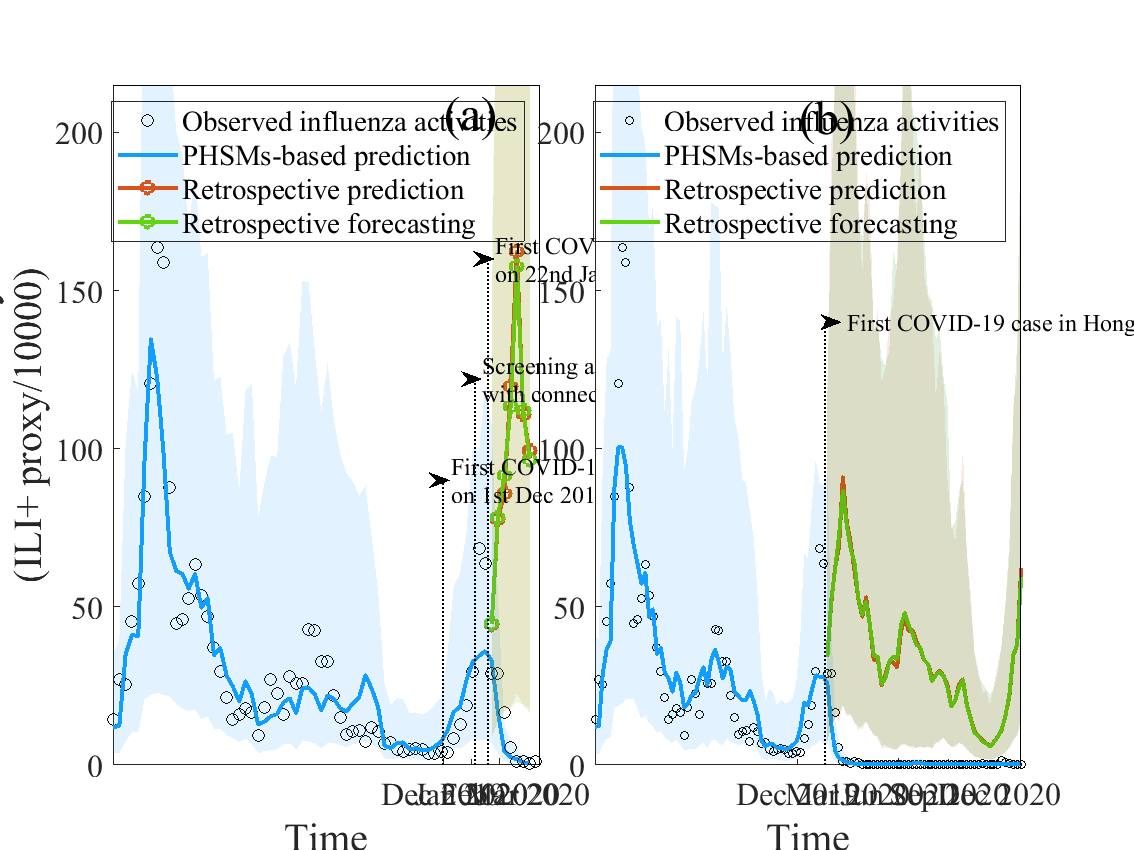

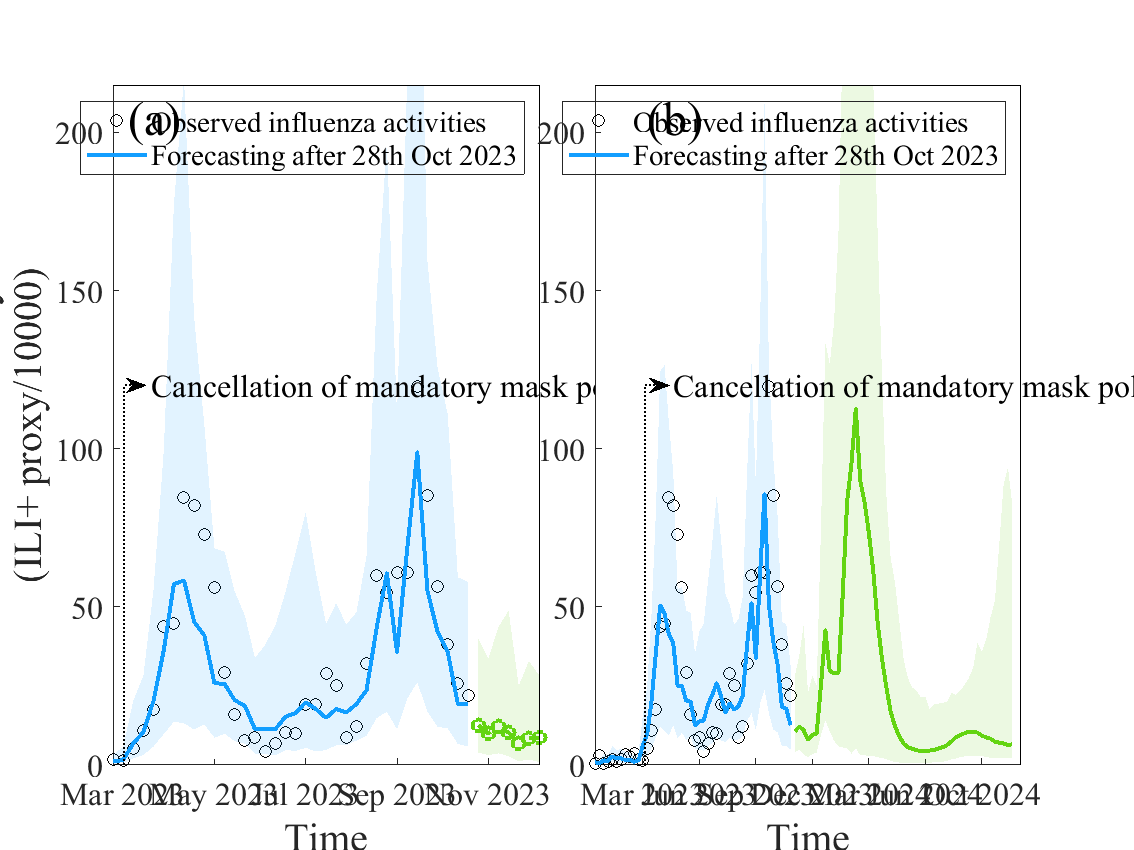

load('ili_proxy_2010_2020.mat')
npistart=525;
Rshort_day = 466:npistart+7; Rshort_day1 = 466:npistart+7; Rshort_day2 = npistart:533; %
Pshort_day1 = 722-52:729; Pshort_day2=677:722;Rshort_day3=526:532;
Rlong_day1 = 466:577;Rlong_day2 = 466:577;Rlong_day3 = 526:577;
PLong_day1 = 677:722;PLong_day2 = 722-52:773;
lims = [0.025,0.5,0.975];%plimshort = plims(R_newPI_short{ENmodel},lims); 
for ENmodel = 5:5
figure();ha=tight_subplot(1,2,0.05,0.1,0.1);
axes(ha(1));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[518.3:4.5:575]);xlim([466,533.5])
set(gca,'xticklabel',{'Dec 2019','Jan 2020','Feb 2020','Mar 2020'},'XTickLabelRotation',0);ylim([0,215]);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
 Rlim_short = plims(R_newPI_short{ENmodel},lims);
 Rlim_shortCF = plims(R_newPI_shortCF{ENmodel},lims);
 Rlim_shortCF_F = plims(R_newPI_shortCF_F{ENmodel},lims);

    plot(Rshort_day1,A(Rshort_day1),'o','LineWidth',0.5,'color',[0,0,0]);   
    plot(Rshort_day,Rlim_short(2,1:end),'-','color',[0.07,0.62,1.00],'LineWidth',2);
    plot(Rshort_day3,Rlim_shortCF(2,2:end),'-o','color',[0.85,0.33,0.10],'LineWidth',2);
    plot(Rshort_day3,Rlim_shortCF_F(2,2:end),'-o','color',[0.39,0.83,0.07],'LineWidth',2);
    % plot(525:526,[A(525) Rlim_shortCF_F(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
    
    plot(Rshort_day2,A(Rshort_day2),'o','LineWidth',0.5,'color',[0,0,0]);
    % plot(525:526,[A(525) Rlim_shortCF(2,2)],':','color',[0.85,0.33,0.10],'LineWidth',2);
    % R_newPI_short{ENmodel}(:,1) = A(npistart);%R_newCI_short{ENmodel}(:,1)= A(525);
    % R_newPI_shortCF{ENmodel}(:,1) = A(npistart);
    % R_newPI_shortCF_F{ENmodel}(:,1) = A(npistart);

   
    fillyy(Rshort_day,Rlim_short(1,:),Rlim_short(3,:),[0.07,0.62,1.00],0.12); %obs 95CI
    fillyy(Rshort_day3,Rlim_shortCF(1,2:end),Rlim_shortCF(3,2:end),[0.85,0.33,0.10],0.12); %obs 95CI
    fillyy(Rshort_day3,Rlim_shortCF_F(1,2:end),Rlim_shortCF_F(3,2:end),[0.39,0.83,0.07],0.12); %obs 95CI
    
plot([525.4 525.4],[0 160],':','color',[0 0 0],'LineWidth',1)
text(526.5,160,sprintf('First COVID-19 case in Hong Kong\non 22nd Jan 2020'),'FontSize',12,'FontName','Times New Roman')
plotarrow(525.4,526.4, 160,160)
plot([523.4 523.4],[0 122],':','color',[0 0 0],'LineWidth',1)
text(524.5,122,sprintf('Screening at airports and train stations\nwith connects to Wuhan on 6th Jan 2020'),'FontSize',12,'FontName','Times New Roman')
plotarrow(523.4,524.4,122,122)
plot([518.3 518.3],[0 90],':','color',[0 0 0],'LineWidth',1)
text(519.5,90,sprintf('First COVID-19 case in Wuhan\non 1st Dec 2019'),'FontSize',12,'FontName','Times New Roman')
text(518.5,206,'(a)',"FontSize",24,'FontName','Times New Roman')
plotarrow(518.3,519.3, 90,90);box_off;
legend('Observed influenza activities','PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
exportgraphics(gcf,'Figure 1 Short_forecasting_A.pdf','ContentType','vector')


axes(ha(2));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');%ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[518.3:13:577]);
set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'},'XTickLabelRotation',0);xlim([466 576]);ylim([0,215]);
set(gca,'ytick',0:50:250);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
Rlim_Long = plims(R_newPI_Long{ENmodel},lims);
Rlim_LongCF = plims(R_newPI_LongCF{ENmodel},lims);
Rlim_LongCF_F = plims(R_newPI_LongCF_F{ENmodel},lims);

plot(Rlong_day1,A(Rlong_day1),'o','MarkerSize',4,'color',[0,0,0]);
plot(Rlong_day2,Rlim_Long(2,1:end),'-','color',[0.07,0.62,1.00],'LineWidth',2);
plot(Rlong_day3,Rlim_LongCF(2,2:end),'-','color',[0.85,0.33,0.10],'LineWidth',2);
plot(Rlong_day3,Rlim_LongCF_F(2,2:end),'-','color',[0.39,0.83,0.07],'LineWidth',2);

% R_newPI_Long{ENmodel}(:,1) = A(npistart);%R_newCI_short{ENmodel}(:,1)= A(525);
% R_newPI_LongCF{ENmodel}(:,1) = A(npistart);
% R_newPI_LongCF_F{ENmodel}(:,1) = A(npistart);

fillyy(Rlong_day2,Rlim_Long(1,:),Rlim_Long(3,:),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(Rlong_day3,Rlim_LongCF(1,2:end),Rlim_LongCF(3,2:end),[0.85,0.33,0.10],0.12); %obs 95CI
fillyy(Rlong_day3,Rlim_LongCF_F(1,2:end),Rlim_LongCF_F(3,2:end),[0 0.5 0],0.12); %obs 95CI

% plot(525:526,[A(525) Rlim_LongCF_F(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
% plot(525:526,[A(525) Rlim_LongCF(2,2)],':','color',[0.85,0.33,0.10],'LineWidth',2);

plot([525.4 525.4],[0 140],':','color',[0 0 0],'LineWidth',1);
text(531,140,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',12,'FontName','Times New Roman');
plotarrow(525.5,529.5,140,140)
text(518.6,205,'(b)',"FontSize",24,'FontName','Times New Roman')
box_off;
legend('Observed influenza activities','PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
exportgraphics(gcf,'Figure 2 Long_forecasting_A.pdf','ContentType','vector')


figure;ha=tight_subplot(1,2,0.05,0.1,0.1);%
axes(ha(1));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[688, 697, 706, 715, 724]);xlim([687 729]);ylim([0,215])
set(gca,'xticklabel',{'Mar 2023','May 2023','Jul 2023','Sep 2023','Nov 2023'},'XTickLabelRotation',0);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
Plim_short = plims(P_newPI_short{ENmodel},lims);
plot(Pshort_day2,A(Pshort_day2),'o','LineWidth',0.5,'color',[0 0 0])
plot(Pshort_day1(2:end-7),Plim_short(2,2:end-7),'-','color',[0.07,0.62,1.00],'LineWidth',2);
plot(Pshort_day1(end-6:end),Plim_short(2,end-6:end),'--o','color',[0.39,0.83,0.07],'LineWidth',2);

% P_newPI_short{ENmodel}(:,1) = A(722);P_newCI_short{ENmodel}(:,1)= A(722);

fillyy(Pshort_day1(2:end-7),Plim_short(1,2:end-7),Plim_short(3,2:end-7),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(Pshort_day1(end-6:end),Plim_short(1,end-6:end),Plim_short(3,end-6:end),[0.39,0.83,0.07],0.12); %obs 95CI

% plot([Pshort_day1(1):Pshort_day1(1)+1],[A(Pshort_day2(end)),Plim_short(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
plot([688.1 688.1],[0 120],':','color',[0 0 0],'LineWidth',1)
text(690.7,120,sprintf('Cancellation of mandatory mask policy'),'FontSize',16,'FontName','Times New Roman')
text(688.5,204.5,'(a)',"FontSize",24,'FontName','Times New Roman')
plotarrow(688.1,690.2,120,120)
box_off
legend('Observed influenza activities','Forecasting after 28th Oct 2023','color','none')
exportgraphics(gcf,'Figure 1 Short_forecasting_B.pdf','ContentType','vector')

axes(ha(2));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');%ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[688 701 714 727 740 753 766]);
set(gca,'xticklabel',{'Mar 2023','Jun 2023','Sep 2023','Dec 2023','Mar 2024','Jun 2024','Oct 2024'},'XTickLabelRotation',0);
xlim([677,775]);ylim([0,215]);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
plot(PLong_day1,A(PLong_day1),'o','LineWidth',0.5,'color',[0 0 0])
% P_newPI_Long{ENmodel}(:,1) = A(722);P_newCI_Long{ENmodel}(:,1)= A(722);
Plim_Long = plims(P_newPI_Long{ENmodel},lims);
plot(PLong_day2(2:end-51),Plim_Long(2,2:end-51),'-','color',[0.07,0.62,1.00],'LineWidth',2);
plot(PLong_day2(end-50:end),Plim_Long(2,end-50:end),'-','color',[0.39,0.83,0.07],'LineWidth',2);

fillyy(PLong_day2(2:end-51),Plim_Long(1,2:end-51),Plim_Long(3,2:end-51),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(PLong_day2(end-50:end),Plim_Long(1,end-50:end),Plim_Long(3,end-50:end),[0.39,0.83,0.07],0.12); %obs 95CI

% plot([PLong_day1(end):PLong_day1(end)+1],[A(PLong_day1(end)),Plim_Long(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
% plot(PLong_day2(2),Plim_Long(2,2),'o','color',[0,0.5,0],'LineWidth',1)
plot([688.5 688.5],[0 120],':','color',[0 0 0],'LineWidth',1)
text(695,120,sprintf('Cancellation of mandatory mask policy'),'FontSize',16,'FontName','Times New Roman')
plotarrow(688.5,694,120,120)
text(689,204.5,'(b)',"FontSize",24,'FontName','Times New Roman');box_off
legend('Observed influenza activities','Forecasting after 28th Oct 2023','color','none')
exportgraphics(gcf,'Figure 2 Long_forecasting_B.pdf','ContentType','vector')
end


% export to vector PDF
% exportgraphics(gcf,'Figure 1 Retrospective_forecasting.pdf','ContentType','vector')
% exportgraphics(gcf,'Figure 2 Prospective_forecasting.pdf','ContentType','vector')

# **compute and analysis**

**I. short-term**

% FIRST-WEEK
First_week_CF = Rlim_shortCF(:,2)
First_week_CF_F = Rlim_shortCF_F(:,2)
decreaseRateshort_CF = (First_week_CF-A(526))./First_week_CF*100
decreaseRateshort_CF_F = (First_week_CF_F-A(526))./First_week_CF_F*100
% Seven-WEEK 
Seven_week_CF = sum(Rlim_shortCF(:,2:8),2)
Seven_week_CF_F = sum(Rlim_shortCF_F(:,2:8),2)
realA = sum(A(526:532));
decreaseRateshort_7CF = (Seven_week_CF-realA)./Seven_week_CF*100
decreaseRateshort_7CF_F = (Seven_week_CF_F-realA)./Seven_week_CF_F*100
max_Seven_week_CF = Rlim_shortCF(:,6)
max_Seven_week_CF_F = Rlim_shortCF_F(:,6)

load('NPI.mat')
load('chain2_2017.mat')
[a,b,c]= CI_mean(1-exp(-chain2(:,11)*mean(NPI(3670:3719))))

a = 0.7594

b = 0.6874

c = 0.8264

**II Short**

FFirst_week_1 = Plim_short(:,2)
FFirst_week_2 = sum(Plim_short(:,2:8),2)
FFirst_week_max = Plim_short(:,8)

**I Long**

Winterpeaktime = 530-525+1;
winter_peak_CF = Rlim_LongCF(:,Winterpeaktime)
winter_peak_CF_F = Rlim_LongCF_F(:,Winterpeaktime)
Attack_winter_real = sum(A(519:535))/10000;
Attack_winter_CF = (sum(A(519:524)) + sum(Rlim_LongCF(:,1:11),2))./10000
Attack_winter_CF_F = (sum(A(519:524)) + sum(Rlim_LongCF_F(:,1:11),2))./10000

decreaseRateLong_CF = (Attack_winter_CF-Attack_winter_real)./Attack_winter_CF
decreaseRateLong_CF_F = (Attack_winter_CF_F-Attack_winter_real)./Attack_winter_CF_F

Summerpeaktime = 550-525+1;
attack_summer_real=sum(A(540:561));
summer_peak_CF = Rlim_LongCF(:,Summerpeaktime)
summer_peak_CF_F = Rlim_LongCF_F(:,Summerpeaktime+1)
Attack_Summer_CF = sum(Rlim_LongCF(:,16:37),2)./10000
Attack_Summer_CF_F = sum(Rlim_LongCF_F(:,16:37),2)./10000

attack_whole_real = sum(A(510:561))/10000;
attack_whole_CF = (sum(A(510:524)) + sum(Rlim_LongCF(:,1:37),2))./10000
attack_whole_CF_F = (sum(A(510:524)) + sum(Rlim_LongCF_F(:,1:37),2))./10000
decreaseRateLong_CF_Fw = (attack_whole_CF_F-attack_whole_real)./attack_whole_CF_F
decreaseRateLong_CFw = (attack_whole_CF-attack_whole_real)./attack_whole_CF


**II Long**

Future_peak_time = 29-12;
future_peak = Plim_Long(:,Future_peak_time)
future_attack_winter = (sum(Plim_Long(:,5:22),2))/10000
Future_peak_time_summer = 46;
future_peak = Plim_Long(:,Future_peak_time_summer)
future_attack_summer = (sum(Plim_Long(:,27:49),2))/10000
future_attack_whole = sum(Plim_Long(:,:),2)/10000


## evaluate year-model

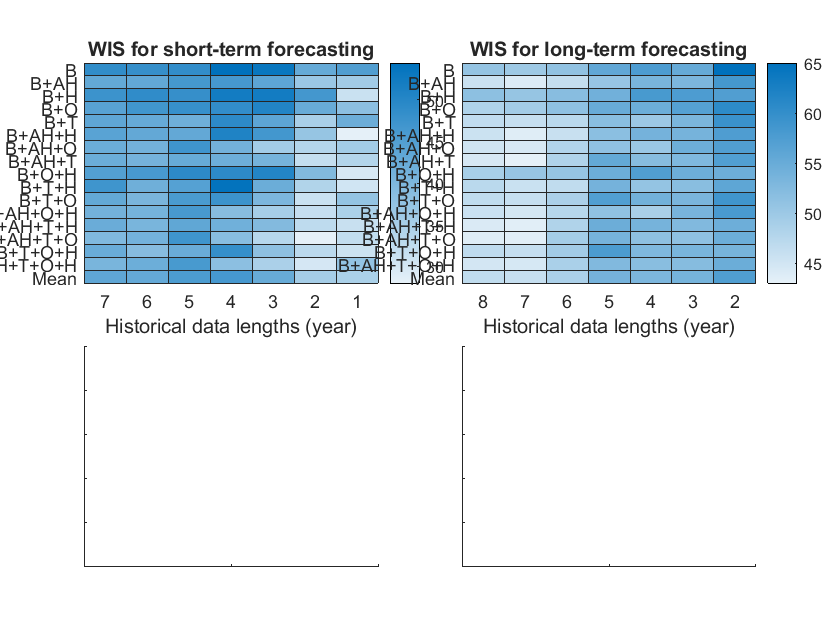

figure();ha =tight_subplot(2,2,0.1,0.1,0.1);
axes(ha(1));%hold on;
Mean_year_Short(17,:) = mean(Mean_year_Short);
yvalues = {'B','B+AH','B+H','B+O','B+T',...
    'B+AH+H','B+AH+O','B+AH+T','B+O+H','B+T+H','B+T+O'...
    'B+AH+O+H','B+AH+T+H','B+AH+T+O','B+T+O+H','B+AH+T+O+H','Mean'};
xvalues = {'7','6','5','4','3','2','1'};

H = heatmap(xvalues,yvalues,Mean_year_Short);
H.YLabel={'Factor-based models'};
H.XLabel = {'Historical data lengths (year)'};
H.Title= {'WIS for short-term forecasting'};

exportgraphics(gcf,'WIS for short forecasting.pdf','ContentType','vector')

axes(ha(2));%hold on;
Mean_year_Long(17,:) = mean(Mean_year_Long);
yvalues = {'B','B+AH','B+H','B+O','B+T',...
    'B+AH+H','B+AH+O','B+AH+T','B+O+H','B+T+H','B+T+O'...
    'B+AH+O+H','B+AH+T+H','B+AH+T+O','B+T+O+H','B+AH+T+O+H','Mean'};
xvalues = {'8','7','6','5','4','3','2'};
H = heatmap(xvalues,yvalues,Mean_year_Long);
%H.YLabel={'Factor-based models'};
 H.XLabel = {'Historical data lengths (year)'};
H.Title= {'WIS for long-term forecasting'};

exportgraphics(gcf,'FigureS 8 WIS for forecasting performance.pdf','ContentType','vector')


Weights_short = [Weights_short_CF{1,1}' Weights_short_CF{1,2}' Weights_short_CF{1,3}' Weights_short_CF{1,4}' Weights_short_CF{1,5}']'

Undefined variable Weights_short_CF.


%figure();ha =tight_subplot(1,2,0.1,0.1,0.1);
axes(ha(3));%hold on;
Weights_short(16,:) = mean(Weights_short);
yvalues = {'B','B+AH','B+H','B+O','B+T',...
    'B+AH+H','B+AH+O','B+AH+T','B+O+H','B+T+H','B+T+O'...
    'B+AH+O+H','B+AH+T+H','B+AH+T+O','B+T+O+H','B+AH+T+O+H'};
xvalues = {'8','7','6','5','4','3','2','1'};

H = heatmap(xvalues,yvalues,Weights_short);
H.YLabel={'Factor-based models'};
H.XLabel = {'Historical data lengths (year)'};
H.Title= {'Weightings for short-term forecasting'};



Weights_long = [Weights_long_CF{1,1}' Weights_long_CF{1,2}' Weights_long_CF{1,3}' Weights_long_CF{1,4}' Weights_long_CF{1,5}']'

axes(ha(4));%hold on;
Weights_long(16,:) = mean(Weights_long);
yvalues = {'B','B+AH','B+H','B+O','B+T',...
    'B+AH+H','B+AH+O','B+AH+T','B+O+H','B+T+H','B+T+O'...
    'B+AH+O+H','B+AH+T+H','B+AH+T+O','B+T+O+H','B+AH+T+O+H'};
xvalues = {'8','7','6','5','4','3','2'};
H = heatmap(xvalues,yvalues,Weights_long);
% H.YLabel={'Factor-based models'};
H.XLabel = {'Historical data lengths (year)'};
H.Title= {'Weightings for long-term forecasting'};

exportgraphics(gcf,'WIS and weightings for long forecasting.pdf','ContentType','vector')






GFH 

%% get model prediction performance
address={'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
scripts1 = [2010:2019];
WIS168=[];
for number1 = 1:numel(address)
   % cd ('F:\Dong\SPH Dropbox\Wang Dong\PC\Modelling_gLobally1');
 %cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1');
 cd('D:\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal')
    cd (address{number1});scripts1 = [2010:2019];
    for job = 1:length(scripts1)
        load(sprintf('ABase_%d.mat',scripts1(job)), 'PIdata','yreal')
        PI=[];
        PI = PIdata(:,1:length(yreal(1:end)))';
        WIS168(number1,job) = weighted_interval_score(PI, yreal(1:end));
    end
end
WIS169=[];
WIS169 = WIS168;
% WIS169(7,1)=67;WIS169(7,7)=90;
WISMODEL = mean(WIS169,2)'

## figure

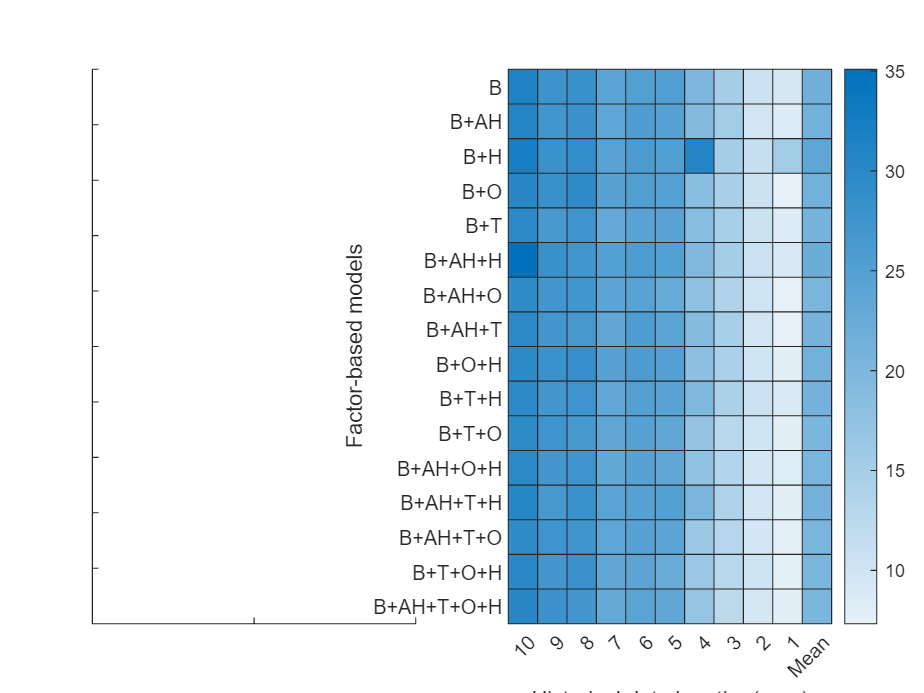

figure;ha =tight_subplot(1,2,0.1,0.1,0.1);
axes(ha(2));%hold on;
WIS169(:,11) = mean(WIS169,2);
yvalues = {'B','B+AH','B+H','B+O','B+T',...
    'B+AH+H','B+AH+O','B+AH+T','B+O+H','B+T+H','B+T+O'...
    'B+AH+O+H','B+AH+T+H','B+AH+T+O','B+T+O+H','B+AH+T+O+H'};
xvalues = {'10','9','8','7','6','5','4','3','2','1','Mean'};
H = heatmap(xvalues,yvalues,WIS169);
H.YLabel={'Factor-based models'};
H.XLabel = {'Historical data lengths (year)'};
exportgraphics(gcf,'WIS for Fitting until now.pdf','ContentType','vector')

%% get model prediction performance
address={'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
scripts1 = [2010:2019];
WIS168=[];
for number1 = 1:numel(address)
 % cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1');
 cd('D:\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal_retro\')
 cd (address{number1});scripts1 = [2010:2019];
 if number1==13
    cd('D:\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal_retro\')
    cd (address{number1});
 end
    for job = 1:length(scripts1)
        % load(sprintf('PICF_Fore_ave_%d.mat',scripts1(job)), 'PIdataCF_Fore')
       PI=[];load(sprintf('ABase_%d.mat',scripts1(job)), "PIdata",'yreal'); 
        PI = PIdata(:,1:length(yreal(1:end-52)))';
        WIS168(number1,job) = weighted_interval_score(PI, yreal(1:end-52));
    end
end
WIS169=[];
WIS169 = WIS168;
% WIS169(7,1)=67;WIS169(7,7)=90;
WISMODEL = mean(WIS169,2)'

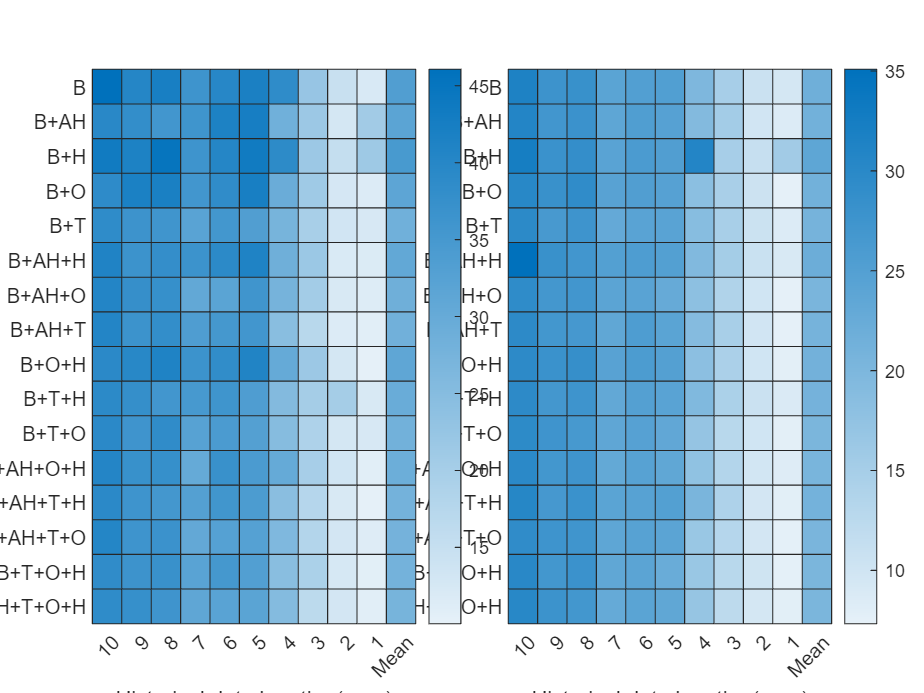

axes(ha(1));%hold on;
WIS169(:,11) = mean(WIS169,2);
yvalues = {'B','B+AH','B+H','B+O','B+T',...
    'B+AH+H','B+AH+O','B+AH+T','B+O+H','B+T+H','B+T+O'...
    'B+AH+O+H','B+AH+T+H','B+AH+T+O','B+T+O+H','B+AH+T+O+H'};
xvalues = {'10','9','8','7','6','5','4','3','2','1','Mean'};
H = heatmap(xvalues,yvalues,WIS169);
H.YLabel={'Factor-based models'};
H.XLabel = {'Historical data lengths (year)'};
exportgraphics(gcf,'WIS for Fitting before pandemic.pdf','ContentType','vector')

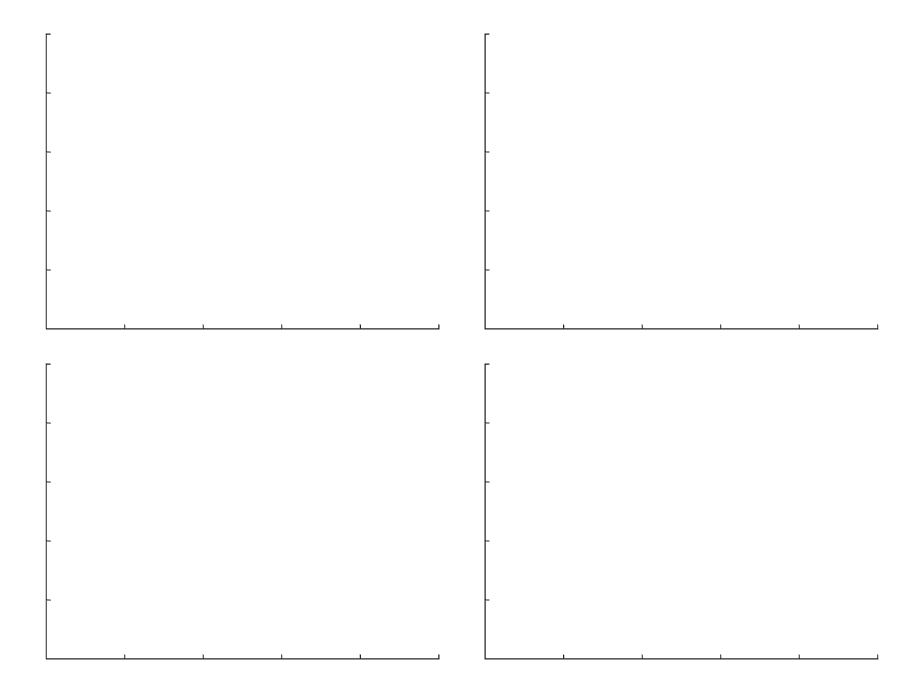

load('ili_proxy_2010_2020.mat')
npistart=525;
Rshort_day = npistart:npistart+7; Rshort_day1 = 518:npistart; Rshort_day2 = npistart:533; %
Pshort_day1 = 722:729; Pshort_day2=688:722;Rshort_day3=526:532;
Rlong_day1 = 517:577;Rlong_day2 = 525:577;Rlong_day3 = 526:577;
PLong_day1 = 687:722;PLong_day2 = 722:773;
lims = [0.025,0.5,0.975];%plimshort = plims(R_newPI_short{ENmodel},lims); 
figure();ha1 =tight_subplot(2,2,0.05,0.05,0.05);%hold on;

figure();ha2 =tight_subplot(2,2,0.05,0.05,0.05);%hold on;


figure();ha4 =tight_subplot(2,2,0.05,0.05,0.05);%hold on;

figs = 0;Name={'(a)','(b)','(c)','(d)'};
figure();ha1 =tight_subplot(2,2,0.05,0.05,0.05);
figure();ha2 =tight_subplot(2,2,0.05,0.05,0.05);

figure();ha3 =tight_subplot(2,2,0.05,0.05,0.05);

figure();ha4 =tight_subplot(2,2,0.05,0.05,0.05);

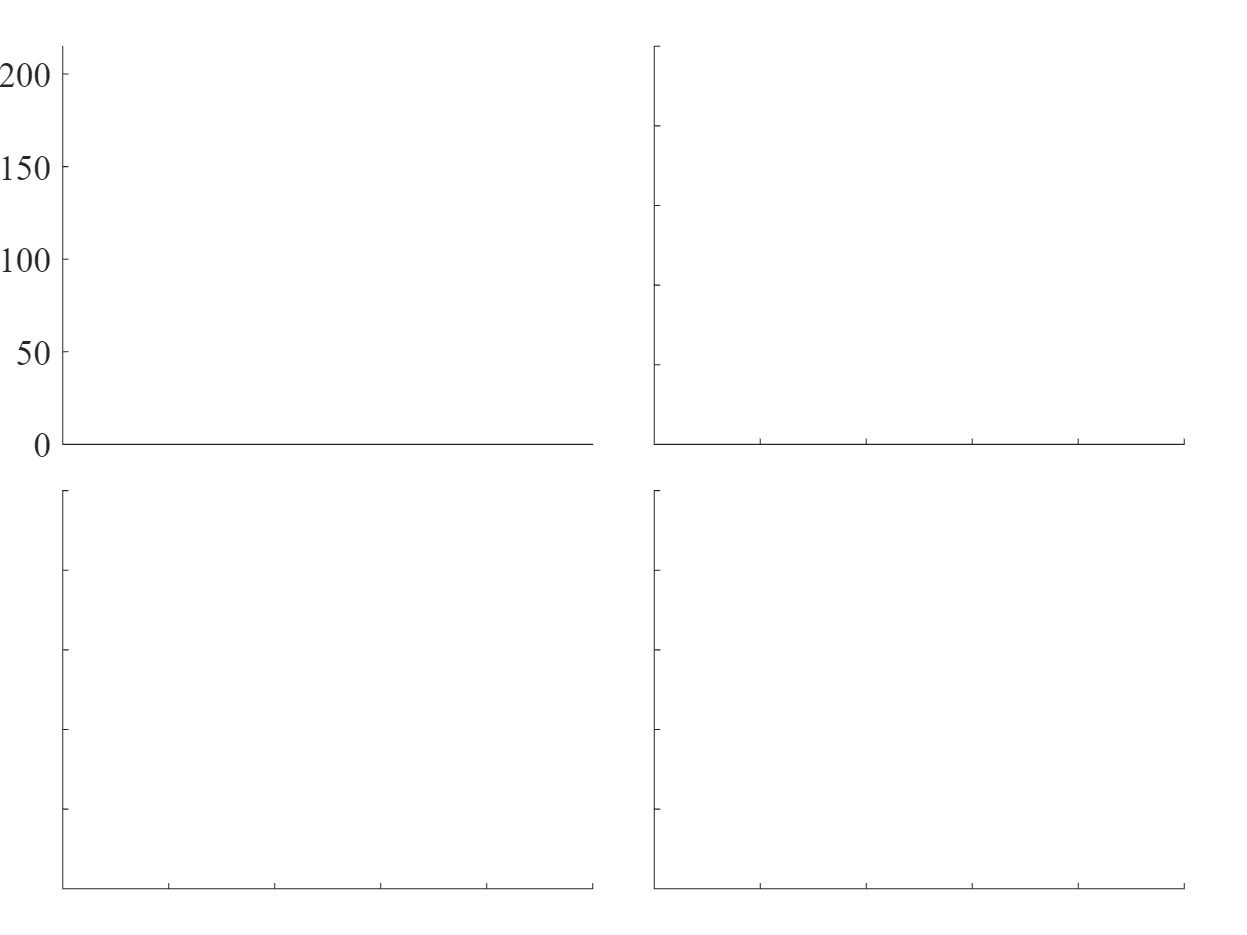

Index exceeds the number of array elements. Index must not exceed 0.

Error in interp1 (line 153)
        extrapMask = Xq < X(1) | Xq > X(end);

Error in plims (line 13)
y = interp1(sort(x),(n-1)*p+1);


for ENmodel = 1:4
    figs=figs+1;
axes(ha1(figs));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
if figs == 3 || figs==4
xlabel('Time');
end
if figs ==1 || figs==3
    ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
end
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[518.3:4.5:575]);
set(gca,'xticklabel',{'Dec 2019','Jan 2020','Feb 2020','Mar 2020'});ylim([0,215]);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
 Rlim_short = plims(R_newPI_short{ENmodel},lims);
 Rlim_shortCF = plims(R_newPI_shortCF{ENmodel},lims);
 Rlim_shortCF_F = plims(R_newPI_shortCF_F{ENmodel},lims);

    plot(Rshort_day,Rlim_short(2,1:end),'-o','color',[0.07,0.62,1.00],'LineWidth',2);
    plot(Rshort_day3,Rlim_shortCF(2,2:end),'-O','color',[0.85,0.33,0.10],'LineWidth',2);
    plot(Rshort_day3,Rlim_shortCF_F(2,2:end),'-o','color',[0.39,0.83,0.07],'LineWidth',2);
    
    plot(Rshort_day1,A(Rshort_day1),'o','LineWidth',0.5,'color',[0,0,0]);
    plot(Rshort_day2,A(Rshort_day2),'o','LineWidth',0.5,'color',[0,0,0]);
    plot(525:526,[A(525) Rlim_shortCF(2,2)],':','color',[0.85,0.33,0.10],'LineWidth',2);
    plot(525:526,[A(525) Rlim_shortCF_F(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
    R_newPI_short{ENmodel}(:,1) = A(npistart);%R_newCI_short{ENmodel}(:,1)= A(525);
    R_newPI_shortCF{ENmodel}(:,1) = A(npistart);
    R_newPI_shortCF_F{ENmodel}(:,1) = A(npistart);

   
    fillyy(Rshort_day,Rlim_short(1,:),Rlim_short(3,:),[0.07,0.62,1.00],0.12); %obs 95CI
    fillyy(Rshort_day3,Rlim_shortCF(1,2:end),Rlim_shortCF(3,2:end),[0.85,0.33,0.10],0.12); %obs 95CI
    fillyy(Rshort_day3,Rlim_shortCF_F(1,2:end),Rlim_shortCF_F(3,2:end),[0.39,0.83,0.07],0.12); %obs 95CI
    
plot([525.4 525.4],[0 160],':','color',[0 0 0],'LineWidth',1)
text(526.5,160,sprintf('First COVID-19 case in Hong Kong\non 22nd Jan 2020'),'FontSize',12,'FontName','Times New Roman')
plotarrow(525.4,526.4, 160,160)
plot([523.4 523.4],[0 122],':','color',[0 0 0],'LineWidth',1)
text(524.5,122,sprintf('Screening at airports and train stations\nwith connects to Wuhan on 6th Jan 2020'),'FontSize',12,'FontName','Times New Roman')
plotarrow(523.4,524.4,122,122)
plot([518.3 518.3],[0 90],':','color',[0 0 0],'LineWidth',1)
text(519.5,90,sprintf('First COVID-19 case in Wuhan\non 1st Dec 2019'),'FontSize',12,'FontName','Times New Roman');
text(515.8,200,Name{ENmodel},"FontSize",24,'FontName','Times New Roman')

plotarrow(518.3,519.3, 90,90);box_off;
legend('PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
exportgraphics(gcf,'FigureS 5 Short_forecasting_sensitivity.pdf','ContentType','vector')


axes(ha2(figs));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
if figs == 3 || figs==4
xlabel('Time');
end
if figs ==1 || figs==3
    ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
end
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[688, 697, 706, 715, 724]);xlim([687 729]);ylim([0,215])
set(gca,'xticklabel',{'Mar 2023','May 2023','Jul 2023','Sep 2023','Nov 2023'},'XTickLabelRotation',0);

set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
Plim_short = plims(P_newPI_short{ENmodel},lims);
plot(Pshort_day2,A(Pshort_day2),'-o','LineWidth',2,'color',[0 0 0])
plot(Pshort_day1(2:end),Plim_short(2,2:end),':O','color',[0.39,0.83,0.07],'LineWidth',2);
P_newPI_short{ENmodel}(:,1) = A(722);P_newCI_short{ENmodel}(:,1)= A(722);

fillyy(Pshort_day1(2:end),Plim_short(1,2:end),Plim_short(3,2:end),[0.39,0.83,0.07],0.12); %obs 95CI
plot([Pshort_day1(1):Pshort_day1(1)+1],[A(Pshort_day2(end)),Plim_short(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
plot([688.1 688.1],[0 120],':','color',[0 0 0],'LineWidth',1)
text(690.7,120,sprintf('Cancellation of mandatory mask policy'),'FontSize',16,'FontName','Times New Roman')
plotarrow(688.1,690.2,120,120);
text(688,200,Name{ENmodel},"FontSize",24,'FontName','Times New Roman')
box_off
% legend('Observed influenza activities','Forecasting after 28th Oct 2023','color','none',Location='northeast')
exportgraphics(gcf,'FigureS 7 Short_forecasting_sensitivity.pdf','ContentType','vector')


axes(ha3(figs));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
if figs == 3 || figs==4
xlabel('Time');
end
if figs ==1 || figs==3
    ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
end
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[518.3:13:577]);
set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'});xlim([516 576]);ylim([0,215]);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
Rlim_Long = plims(R_newPI_Long{ENmodel},lims);
Rlim_LongCF = plims(R_newPI_LongCF{ENmodel},lims);
Rlim_LongCF_F = plims(R_newPI_LongCF_F{ENmodel},lims);

plot(Rlong_day1,A(Rlong_day1),'o','MarkerSize',4,'color',[0,0,0]);
plot(Rlong_day2,Rlim_Long(2,1:end),'-','color',[0.07,0.62,1.00],'LineWidth',2);
plot(Rlong_day3,Rlim_LongCF(2,2:end),'-','color',[0.85,0.33,0.10],'LineWidth',2);
plot(Rlong_day3,Rlim_LongCF_F(2,2:end),'-','color',[0.39,0.83,0.07],'LineWidth',2);

R_newPI_Long{ENmodel}(:,1) = A(npistart);%R_newCI_short{ENmodel}(:,1)= A(525);
R_newPI_LongCF{ENmodel}(:,1) = A(npistart);
R_newPI_LongCF_F{ENmodel}(:,1) = A(npistart);

fillyy(Rlong_day2,Rlim_Long(1,:),Rlim_Long(3,:),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(Rlong_day3,Rlim_LongCF(1,2:end),Rlim_LongCF(3,2:end),[0.85,0.33,0.10],0.12); %obs 95CI
fillyy(Rlong_day3,Rlim_LongCF_F(1,2:end),Rlim_LongCF_F(3,2:end),[0 0.5 0],0.12); %obs 95CI

plot(525:526,[A(525) Rlim_LongCF(2,2)],':','color',[0.85,0.33,0.10],'LineWidth',2);
plot(525:526,[A(525) Rlim_LongCF_F(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);


plot([525.4 525.4],[0 140],':','color',[0 0 0],'LineWidth',1);
text(531,140,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',12,'FontName','Times New Roman');
plotarrow(525.5,529.5,140,140)
box_off;
% legend('Observed influenza activities','PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none',Location='northeast');
text(518,200,Name{ENmodel},"FontSize",24,'FontName','Times New Roman')

exportgraphics(gcf,'FigureS 6 Long_forecasting_sensitivity.pdf','ContentType','vector')


axes(ha4(figs));hold on;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
if figs == 3 || figs==4
xlabel('Time');
end
if figs ==1 || figs==3
    ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
end
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[688 701 714 727 740 753 766]);
set(gca,'xticklabel',{'Mar 2023','Jun 2023','Sep 2023','Dec 2023','Mar 2024','Jun 2024','Oct 2024'},'XTickLabelRotation',0);

xlim([687,775]);ylim([0,215]);
set(gca,'ytick',[0:50:250]);
set(gca,'yticklabel',{'0','50','100','150','200','250'});
plot(PLong_day1,A(PLong_day1),'LineWidth',2,'color',[0 0 0])
P_newPI_Long{ENmodel}(:,1) = A(722);P_newCI_Long{ENmodel}(:,1)= A(722);
Plim_Long = plims(P_newPI_Long{ENmodel},lims);
plot(PLong_day2(2:end),Plim_Long(2,2:end),':','color',[0.39,0.83,0.07],'LineWidth',2);

fillyy(PLong_day2(2:end),Plim_Long(1,2:end),Plim_Long(3,2:end),[0.39,0.83,0.07],0.12); %obs 95CI
plot([PLong_day1(end):PLong_day1(end)+1],[A(PLong_day1(end)),Plim_Long(2,2)],':','color',[0.39,0.83,0.07],'LineWidth',2);
% plot(PLong_day2(2),Plim_Long(2,2),'o','color',[0,0.5,0],'LineWidth',1)
plot([688.5 688.5],[0 120],':','color',[0 0 0],'LineWidth',1)
text(695,120,sprintf('Cancellation of mandatory mask policy'),'FontSize',16,'FontName','Times New Roman')
plotarrow(688.5,694,120,120);
text(689,200,Name{ENmodel},"FontSize",24,'FontName','Times New Roman')

box_off
% legend('Observed influenza activities','Forecasting after 28th Oct 2023','color','none',Location='northeast')
exportgraphics(gcf,'FigureS 8 Long_forecasting_sensitivity.pdf','ContentType','vector')

end

# get ensemble transmission rates

% model_number={[1],[2:5],[6:11],[12:15],[16]};
% EN_valueslong_CF   = [7,28,42,28,7];
% yearlong_CF        =[2012,2013,2014,2015,2016,2017,2018];
% Ranks_Long_CF=[];
% yearlong_P       = [2015,2016,2017,2018,2019];
% EN_valueslong_P  = [5,20,30,20,5];
% 
% 
% Ranks_Long_P=[];
% Weights_long_CF=[];Weights_long_P=[];
% for ENmodel = 1:5
% Ranks_Long_CF{ENmodel}  = Mean_year_Long(model_number{ENmodel},:);
% Ranks_Long_P{ENmodel}  = Mean_year_Long(model_number{ENmodel},1:5);
% [~,C1L_CF]=sort(Ranks_Long_CF{ENmodel}(:));[~,F1L_CF]=sort(C1L_CF(:)); Ranks_Long_CF{ENmodel}=reshape(F1L_CF,length(model_number{ENmodel}),7);
% [~,C1L_P]=sort(Ranks_Long_P{ENmodel}(:));[~,F1L_P]=sort(C1L_P(:)); Ranks_Long_P{ENmodel}=reshape(F1L_P,length(model_number{ENmodel}),5);
% for col=1:length(yearlong_CF)
%     for row=1:numel(Model_scripts(model_number{ENmodel}))
%         Weights_long_CF{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_CF(ENmodel),Ranks_Long_CF{ENmodel}(row,col));
%     end
% end
% for col=1:length(yearlong_P)
%     for row=1:numel(Model_scripts(model_number{ENmodel}))
%         Weights_long_P{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_P(ENmodel),Ranks_Long_P{ENmodel}(row,col));
%     end
% end
% sum(sum(Weights_long_CF{ENmodel}))
% sum(sum(Weights_long_P{ENmodel}))
% end
% 
% for ENmodel = 1:5
% N = 10000;
% R_newPI_Long{ENmodel}=zeros(394,N);
% R_newPI_LongCF{ENmodel}=zeros(394,N);
% R_newPI_LongCF_F{ENmodel}=zeros(394,N);
% P_newPI_Long{ENmodel}=zeros(394,N);
% for row=1:numel(Model_scripts(model_number{ENmodel}))
%     % cd('F:\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
%     cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
%     cd(Model_scripts{model_number{ENmodel}(row)});
%     for col=1:length(yearlong_CF)
%         load(sprintf('Re_%d.mat',yearlong_CF(col)));
%         R_newPI_Long{ENmodel}    = R_newPI_Long{ENmodel} + Weights_long_CF{ENmodel}(row,col).*ReR(1:394,1:N);
%         R_newPI_LongCF{ENmodel}  = R_newPI_LongCF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*ReC1(1:394,1:N);
%         R_newPI_LongCF_F{ENmodel}  = R_newPI_LongCF_F{ENmodel} + Weights_long_CF{ENmodel}(row,col).*ReC2(1:394,1:N);
%     end
%     for col=1:length(yearlong_P)
%         load(sprintf('Re_%d.mat',yearlong_P(col)));
%         P_newPI_Long{ENmodel}    = P_newPI_Long{ENmodel} + Weights_long_P{ENmodel}(row,col).*ReR1(1:394,1:N);
%     end
% end
% end

% yearlong_P       = [2015,2016,2017,2018,2019];
% for ENmodel = 1:5
% for row=1:numel(Model_scripts(model_number{ENmodel}))
%   %  cd('F:\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
%      cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
%     cd(Model_scripts{model_number{ENmodel}(row)});
% N = 1000;
% R_newPI_LongS{ENmodel}=zeros(N,394);R_newPI_LongV{ENmodel}=zeros(N,394);R_newPI_LongR{ENmodel}=zeros(N,394);
% R_newPI_LongCFSF{ENmodel}=zeros(N,394);R_newPI_LongCFVF{ENmodel}=zeros(N,394);R_newPI_LongCFRF{ENmodel}=zeros(N,394);
% R_newPI_LongCFS{ENmodel}=zeros(N,394);R_newPI_LongCFV{ENmodel}=zeros(N,394);R_newPI_LongCFR{ENmodel}=zeros(N,394);
% P_newPI_LongS{ENmodel}=zeros(N,394);P_newPI_LongV{ENmodel}=zeros(N,394);P_newPI_LongR{ENmodel}=zeros(N,394);
% 
%     for col=1:length(yearlong_CF)
%         load(sprintf('SRV_Comparetements_%d.mat',yearlong_CF(col)));
%         R_newPI_LongS{ENmodel}    = R_newPI_LongS{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CSR(1:N,3627:4020);
%         % R_newPI_LongV{ENmodel}    = R_newPI_LongV{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CVR(:,3627:4020);
%         % R_newPI_LongR{ENmodel}    = R_newPI_LongR{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CRR(:,3627:4020);
%         R_newPI_LongCFSF{ENmodel}  = R_newPI_LongCFSF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CSCF(1:N,3627:4020);
%         % R_newPI_LongCFVF{ENmodel}  = R_newPI_LongCFVF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CVCF(:,3627:4020);
%         % R_newPI_LongCFRF{ENmodel}  = R_newPI_LongCFRF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CRCF(:,3627:4020);
%         load(sprintf('SRV_Comparetements_CF_%d.mat',yearlong_CF(col)));
%         R_newPI_LongCFS{ENmodel}  = R_newPI_LongCFS{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CSCF(1:N,3627:4020);
%         % R_newPI_LongCFV{ENmodel}  = R_newPI_LongCFV{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CVCF(:,3627:4020);
%         % R_newPI_LongCFR{ENmodel}  = R_newPI_LongCFR{ENmodel} + Weights_long_CF{ENmodel}(row,col).*CRCF(:,3627:4020);
%     end
%     for col=1:length(yearlong_P)
%         load(sprintf('SRV_Comparetements_%d.mat',yearlong_P(col)),'CSR','CVR','CRR');
%         P_newPI_LongS{ENmodel}    = P_newPI_LongS{ENmodel} + Weights_long_P{ENmodel}(row,col).*CSR(1:N,end-393:end);
%         % P_newPI_LongV{ENmodel}    = P_newPI_LongV{ENmodel} + Weights_long_P{ENmodel}(row,col).*CVR(:,end-393:end);
%         % P_newPI_LongR{ENmodel}    = P_newPI_LongR{ENmodel} + Weights_long_P{ENmodel}(row,col).*CRR(:,end-393:end);
%     end
% end
% end
%     % plot(Rshort_day,Rlim_short(2,1:end),'-o','color',[0.07,0.62,1.00],'LineWidth',2);
%     % plot(Rshort_day3,Rlim_shortCF(2,2:end),'-O','color',[0.85,0.33,0.10],'LineWidth',2);
%     % plot(Rshort_day3,Rlim_shortCF_F(2,2:end),'-o','color',[0.39,0.83,0.07],'LineWidth',2);

% figs = 0;Name={'(a)','(b)','(c)','(d)'};
% for ENmodel = 1:5
%     figs=figs+1;
% figure;ha =tight_subplot(2,2,0.1,0.1,0.1);
% axes(ha(1));hold on;
% F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',18);
% ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',24);
% set(get(gca,'XLabel'),'FontSize',24);
% set(gca,'xtick',[1:90:394]);
% % set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'});
% xlim([1 365]);
% set(gca,'ytick',[0,0.1,0.2,0.3,0.4,0.5,0.6]);
% set(gca,'yticklabel',{'0','0.1','0.2','0.3','0.4','0.5','0.6'});
% [beta1,day1,meanbeta]= modelCI(F_day1,R_newPI_Long{ENmodel});
% plot (F_day1,meanbeta,'LineWidth',1.5,'color',[0.07,0.62,1.00])
% [beta2,day1,meanbeta2]= modelCI(F_day1,R_newPI_LongCF{ENmodel});
% plot (F_day1,meanbeta2,'LineWidth',1.5,'Color',[0.85,0.33,0.10])
% [beta3,day1,meanbeta3]= modelCI(F_day1,R_newPI_LongCF_F{ENmodel});
% plot (F_day1,meanbeta3,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
% H_F1=fill(day1,beta3,[0.39,0.83,0.07],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,beta1,[0.07,0.62,1.00],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,beta2,[0.85,0.33,0.10],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});
% ylabel('\beta(t)');set(legend,'color','none','Box', 'on'); 
% plot([39 39],[0 0.25],':','color',[0 0 0],'LineWidth',1);
% text(75,0.25,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',10,'FontName','Times New Roman');
% plotarrow(39,70,0.25,0.25)
% legend('PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
% text(23,0.25,'(a)',"FontSize",20,'FontName','Times New Roman')
% box_off;legend('PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
% 
% 
% axes(ha(2));hold on;F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',18);
% ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',24);
% set(get(gca,'XLabel'),'FontSize',24);
% set(gca,'xtick',[28:90:394]);
% % set(gca,'xticklabel',{'Jun 2023', 'Sep 2023', 'Dec 2023', 'Mar 2024', 'Jun 2024'});xlim([1 365]);
% [beta1,day1,meanbeta]= modelCI(F_day1,P_newPI_Long{ENmodel});
% plot (F_day1,meanbeta,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
% H_F1=fill(day1,beta1,[0.39,0.83,0.07],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});
% ylabel('\beta(t)');
% set(gca,'ytick',[0,0.1,0.2,0.3,0.4,0.5,0.6,0.7]);
% set(gca,'yticklabel',{'0','0.1','0.2','0.3','0.4','0.5','0.6','0.7'});
% text(20,0.25,'(b)',"FontSize",20,'FontName','Times New Roman')
% box_off;legend('Prospective forecasting','color','none');set(legend,'color','none','Box', 'on'); 
% 
% axes(ha(3));hold on;F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',20);
% set(get(gca,'XLabel'),'FontSize',20);
% set(gca,'xtick',[10:90:394]);
% set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'},'XTickLabelRotation',0);xlim([10 375]);ylim([0.39 0.8]);
% % set(gca,'ytick',[0.1,0.2,0.3,0.4,0.5]);
% % set(gca,'yticklabel',{'0.1','0.2','0.3','0.4','0.5'});
% [betaS,day1,meanbetaS]= modelCI(F_day1,R_newPI_LongS{ENmodel}');
% [betaS1,day1,meanbetaS1]= modelCI(F_day1,R_newPI_LongCFSF{ENmodel}');
% [betaS2,day1,meanbetaS2]= modelCI(F_day1,R_newPI_LongCFS{ENmodel}');
% plot(F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.07,0.62,1.00])
% plot(F_day1,meanbetaS1,'LineWidth',1.5,'Color',[0.85,0.33,0.10])
% plot(F_day1,meanbetaS2,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
% H_F1=fill(day1,betaS,[0.07,0.62,1.00],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,betaS2,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,betaS1,[0.85,0.33,0.10],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% plot([48 48],[0 0.25],':','color',[0 0 0],'LineWidth',1);
% text(75,0.65,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',10,'FontName','Times New Roman');
% text(23,0.27,'(c)',"FontSize",20,'FontName','Times New Roman')
% box_off;legend('PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
% set(legend,'color','none','Box', 'on'); plotarrow(48,70,0.65,0.55);
% 
% axes(ha(4));hold on;F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',20);
% set(get(gca,'XLabel'),'FontSize',20);
% set(gca,'xtick',[28:90:414]);
% set(gca,'xticklabel',{'Nov 2023', 'Jan 2024', 'Apr 2024', 'Jul 2024', 'Oct 2024'},'XTickLabelRotation',0);
% [betaS,day1,meanbetaS]= modelCI(F_day1,P_newPI_LongS{ENmodel}');
% plot (F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
% H_F1=fill(day1,betaS,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% xlim([28 394]);ylim([0.2 0.5]);
% % set(gca,'ytick',[0.0,0.1,0.2,0.3]);
% % set(gca,'yticklabel',{'0.1','0.1','0.2','0.3'});
% text(40,0.27,'(d)',"FontSize",20,'FontName','Times New Roman');
% box_off;
% legend('Prospective forecasting','color','none')
% set(legend,'color','none','Box', 'on'); 
% end
% 
% 
% 
% 
% 
% 
% 

# Figure below

% 
% 

% for row=1:numel(Model_scripts(model_number{ENmodel}))
% axes(ha(3));hold on;F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',20);
% set(get(gca,'XLabel'),'FontSize',20);
% set(gca,'xtick',[10:90:394]);
% set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'},'XTickLabelRotation',0);xlim([10 375]);ylim([0.39 0.8]);
% set(gca,'ytick',[0.4,0.5,0.6,0.7,0.8]);
% set(gca,'yticklabel',{'0.4','0.5','0.6','0.7','0.8'});
% 
% [betaS,day1,meanbetaS]= modelCI(F_day1,R_newPI_LongS{ENmodel}');
% [betaS1,day1,meanbetaS1]= modelCI(F_day1,R_newPI_LongCFSF{ENmodel}');
% [betaS2,day1,meanbetaS2]= modelCI(F_day1,R_newPI_LongCFS{ENmodel}');
% 
% plot (F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.07,0.62,1.00])
% plot (F_day1,meanbetaS1,'LineWidth',1.5,'Color',[0.85,0.33,0.10])
% plot (F_day1,meanbetaS2,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
% 
% H_F1=fill(day1,betaS,[0.07,0.62,1.00],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,betaS2,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,betaS1,[0.85,0.33,0.10],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% plot([48 48],[0 0.65],':','color',[0 0 0],'LineWidth',1);
% text(75,0.65,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',10,'FontName','Times New Roman');
% plotarrow(48,70,0.65,0.65)
% text(23,0.77,'(c)',"FontSize",20,'FontName','Times New Roman')
% box_off;
% % legend('PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none',Location='northeast')
% set(legend,'color','none','Box', 'on'); 
% 
% axes(ha(4));hold on;F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',20);
% set(get(gca,'XLabel'),'FontSize',20);
% set(gca,'xtick',[28:90:414]);
% set(gca,'xticklabel',{'Nov 2023', 'Jan 2024', 'Apr 2024', 'Jul 2024', 'Oct 2024'},'XTickLabelRotation',0);
% [betaS,day1,meanbetaS]= modelCI(F_day1,P_newPI_LongS{ENmodel}');
% plot (F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
% H_F1=fill(day1,betaS,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% xlim([28 394]);ylim([0.2 0.5]);
% set(gca,'ytick',[0.2,0.3,0.4,0.5]);
% set(gca,'yticklabel',{'0.2','0.3','0.4','0.5'});
% box_off;
% text(40,0.47,'(d)',"FontSize",20,'FontName','Times New Roman')
% legend('Prospective forecasting','color','none',Location='northeast')
% set(legend,'color','none','Box', 'on'); 
% end
% %exportgraphics(gcf,'FIGURE 3 SUSCEPTIBLITY_transmission_rate.pdf','ContentType','vector')

# Sensitivity with PHSMs

% 
% for ENmodel = 5:5
% Ranks_short_P{ENmodel} = Mean_year_Short(model_number{ENmodel},1:5);
% Ranks_Long_P{ENmodel}  = Mean_year_Long(model_number{ENmodel},1:5);
% [~,C1S_P]=sort(Ranks_short_P{ENmodel}(:));[~,F1S_P]=sort(C1S_P(:)); Ranks_short_P{ENmodel}=reshape(F1S_P,length(model_number{ENmodel}),5);
% [~,C1L_P]=sort(Ranks_Long_P{ENmodel}(:));[~,F1L_P]=sort(C1L_P(:)); Ranks_Long_P{ENmodel}=reshape(F1L_P,length(model_number{ENmodel}),5);
% Weights_long_CF=[];Weights_short_CF=[];Weights_long_P=[];Weights_short_P=[];
% for col=1:length(yearshort_P)
%     for row=1:numel(Model_scripts(model_number{ENmodel}))
%         Weights_short_P{ENmodel}(row,col)= rank_order_centroid_weighting(EN_valuesshort_P(ENmodel),Ranks_short_P{ENmodel}(row,col));
%         Weights_long_P{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_P(ENmodel),Ranks_Long_P{ENmodel}(row,col));
%     end
% end
% 
% sum(sum(Weights_short_P{ENmodel}))
% sum(sum(Weights_long_P{ENmodel}))
% 
% N = 1000;
% PHSMS_SCRIPT = [0,5,10];
% for PHSMS = 1:3
%     P_newPI_short{PHSMS}=zeros(N,8);P_newPI_Long{PHSMS}=zeros(N,52);
%     P_newCI_short{PHSMS}=zeros(N,8);P_newCI_Long{PHSMS}=zeros(N,52); 
% for row=1:numel(Model_scripts(model_number{ENmodel}))
%     if PHSMS == 1
%         for col=1:length(yearshort_P)
%             load(sprintf('ABase_%d.mat',yearshort_P(col)),'PIdata');
%             P_newPI_short{PHSMS}   = P_newPI_short{PHSMS}  + Weights_short_P{ENmodel}(row,col).*PIdata(1:N,end-52:end-45);
%             P_newPI_Long{PHSMS}    = P_newPI_Long{PHSMS} + Weights_long_P{ENmodel}(row,col).*PIdata(1:N,end-51:end);
%         end
%     else 
%         for col=1:length(yearshort_P)
%             load(sprintf('PICF_Fore_NPI%d_%d.mat',PHSMS_SCRIPT(PHSMS),yearshort_P(col)),'PIdataCF_Fore');
%             P_newPI_short{PHSMS}   = P_newPI_short{PHSMS}  + Weights_short_P{ENmodel}(row,col).*PIdataCF_Fore(1:N,end-52:end-45);
%             P_newPI_Long{PHSMS}    = P_newPI_Long{PHSMS} + Weights_long_P{ENmodel}(row,col).*PIdataCF_Fore(1:N,end-51:end);
%         end
% 
%     end
% end
% end
% end
% 

% 
% load('ili_proxy_2010_2020.mat')
% npistart=525;
% Pshort_day1 = 722:729; Pshort_day2=701:722;Rshort_day3=526:532;
% PLong_day1 = 699:722;PLong_day2 = 722:773;
% lims = [0.025,0.5,0.975];%plimshort = plims(R_newPI_short{ENmodel},lims);
% figure;ha =tight_subplot(1,2,0.1,0.1,0.1);
% axes(ha(1));hold on;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
% set(get(gca,'YLabel'),'FontSize',20);set(get(gca,'XLabel'),'FontSize',20);
% set(gca,'xtick',[688 697 706, 715]);xlim([687 716]);ylim([0,215])
% set(gca,'xticklabel',{'Mar 2023','May 2023','Jul 2023','Sep 2023'},'XTickLabelRotation',0);
% set(gca,'ytick',[0:50:250]);
% set(gca,'yticklabel',{'0','50','100','150','200','250'});
% plot(Pshort_day2,A(Pshort_day2),'-o','LineWidth',2,'color',[0 0 0])
% colors =[[0.39,0.83,0.07];[0.07,0.62,1.00];[0.85,0.33,0.10]];
% for ENmodel = 1:3
% Plim_short{ENmodel} = plims(P_newPI_short{ENmodel},lims);
% plot(Pshort_day1(2:end),Plim_short{ENmodel}(2,2:end),':O','color',colors(ENmodel,:),'LineWidth',2);
% end
% for ENmodel = 1:3
% P_newPI_short{ENmodel}(:,1) = A(722);P_newCI_short{ENmodel}(:,1)= A(722);
% fillyy(Pshort_day1(2:end),Plim_short{ENmodel}(1,2:end),Plim_short{ENmodel}(3,2:end),colors(ENmodel,:),0.12); %obs 95CI
% plot([Pshort_day1(1):Pshort_day1(1)+1],[A(Pshort_day2(end)),Plim_short{ENmodel}(2,2)],':','color',colors(ENmodel,:),'LineWidth',2);
% plot([688.1 688.1],[0 120],':','color',[0 0 0],'LineWidth',1)
% end
% text(690.7,120,sprintf('Cancellation of mandatory mask policy'),'FontSize',16,'FontName','Times New Roman')
% plotarrow(688.1,690.2,120,120);box_off;
% legend('Observed influenza activities','PHSMs = 0','PHSMs = 5','PHSMs = 10','color','none')
% 
% 
% axes(ha(2));hold on;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Influenza activity\n(ILI+ proxy/10000)'));
% set(get(gca,'YLabel'),'FontSize',20);
% set(get(gca,'XLabel'),'FontSize',20);
% set(gca,'xtick',[688 701 714 727 740 753]);
% set(gca,'xticklabel',{'Mar 2023','Jun 2023','Sep 2023','Dec 2023','Mar 2024','Jun 2024'},'XTickLabelRotation',0);
% xlim([687,775]);ylim([0,215]);
% set(gca,'ytick',[0:50:250]);
% set(gca,'yticklabel',{'0','50','100','150','200','250'});
% plot(PLong_day1,A(PLong_day1),'LineWidth',2,'color',[0 0 0])
% Plim_Long=[];
% for ENmodel = 1:3
% P_newPI_Long{ENmodel}(:,1) = A(722);P_newCI_Long{ENmodel}(:,1)= A(722);
% Plim_Long{ENmodel} = plims(P_newPI_Long{ENmodel},lims);
% plot(PLong_day2(2:end),Plim_Long{ENmodel}(2,2:end),'-','color',colors(ENmodel,:),'LineWidth',2);
% end
% 
% for ENmodel = 1:3
% fillyy(PLong_day2(2:end),Plim_Long{ENmodel}(1,2:end),Plim_Long{ENmodel}(3,2:end),colors(ENmodel,:),0.12); %obs 95CI
% plot([PLong_day1(end):PLong_day1(end)+1],[A(PLong_day1(end)),Plim_Long{ENmodel}(2,2)],':','color',colors(ENmodel,:),'LineWidth',2);
% % plot(PLong_day2(2),Plim_Long(2,2),'o','color',[0,0.5,0],'LineWidth',1)
% plot([688.5 688.5],[0 120],':','color',[0 0 0],'LineWidth',1)
% end
% 
% text(695,120,sprintf('Cancellation of mandatory mask policy'),'FontSize',16,'FontName','Times New Roman')
% plotarrow(688.5,694,120,120)
% box_off
% legend('Observed influenza activities','PHSMs = 0','PHSMs = 5','PHSMs = 10','color','none')
% exportgraphics(gcf,'FigureS 16 Future_influenza_PHSMs.pdf','ContentType','vector')

% for col=1:length(yearshort_CF)
%     for row=1:numel(Model_scripts(model_number{ENmodel}))
%         Table1s(row,col)='('+Table1s(row,col) + ',';
%         Table2s(row,col)=Table2s(row,col) + ')';
%         Table1L(row,col)='('+Table1L(row,col) + ',';
%         Table2L(row,col)=Table2L(row,col) + ')';
%     end
% end
% TABLE_S = strcat(Table1s,Table2s);
% TABLE_L = strcat(Table1L,Table2L);
% 
% 
% [D_S,C_s]=sort(Ranks_short_CF{ENmodel});[~,Ranks_short_CF{ENmodel}]=sort(C_s);
% Table1s = string(round(Mean_year_Short(model_number{ENmodel},:),2));Table2s = string(Ranks_short_CF{ENmodel});
% [D_L,C_l]=sort(Ranks_Long_CF{ENmodel});[~,Ranks_Long_CF{ENmodel}]=sort(C_l);
% Table1L = string(round(Mean_year_Long(model_number{ENmodel},:),2));Table2L= string(Ranks_Long_CF{ENmodel});
% 
% 
% 

% scripts = [2010:1:2019];
% for number = 1:numel({'_5Base+AH+T+O+H'})
%    % cd ('F:\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end')
%     %cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
%     %cd ('_5Base+AH+T+O+H'); 
%     for jth=1:10
%         close all
% modelfun = @(d,th) f3(d(:,1),th,d);
% load(sprintf('ABase_%d.mat',scripts(jth)));
% chain1 = chain2; chain1(:,11)=0;
% [CSCF,CRCF,CVCF,CSR,CRR,CVR] =deal([]); %CSR,CRR,CVR
% [~,~,~,CSCF,CVCF,CRCF]= mcmcpred(results2,chain1,s2chain2,[start:774]',modelfun,nsample); 
% [~,~,~,CSR,CVR,CRR]= mcmcpred(results2,chain2,s2chain2,[start:774]',modelfun,nsample);
% save(sprintf('SRV_Comparetements_%d.mat',scripts(jth)),'CSCF','CRCF','CVCF','CSR','CRR','CVR')
% %save(sprintf('SRV_Comparetements_CF_%d.mat',scripts(j)),'CSCF','CRCF','CVCF')
% jth
%     end
% end







